**Traitement des données électromyographique (FUNCTIONAL)**

Contexte : analyse des données des tâches motrices **fonctionelles** sur 7 muscles de l'épaule lors de différentes actions : 

- FUNCTIONAL1 : porter les mains à la bouche

- FUNCTIONAL2 : toucher le haut de la tête

- FUNCTIONAL3 : porter les mains le plus haut possible au-dessus de la tête

- FUNCTIONAL4 : porter les mains le plus haut possible le long de la colonne vertébrale

Paramètres

clc; clear all; 

% Ajout de la bibliothèque btk 
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Toolboxs\btk'));

% Définition sujet

% SAINS
subjects = {'A1'}; % 1-41

% PRE-OPERATOIRE
subjects = {'S1'}; % 1-41

% POST-OPERATOIRE
subjects = {'S1'}; % 1-41

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'LLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};

% Définition des functionals
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'
    };

Echelle normalisée pour tous les muscles (visualisation globale du signal)

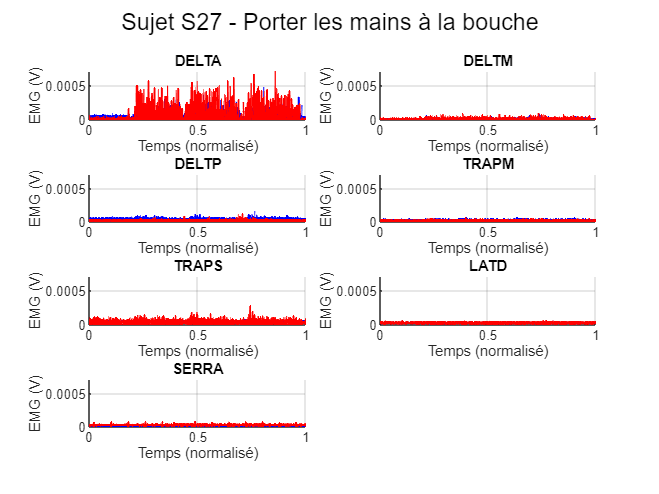

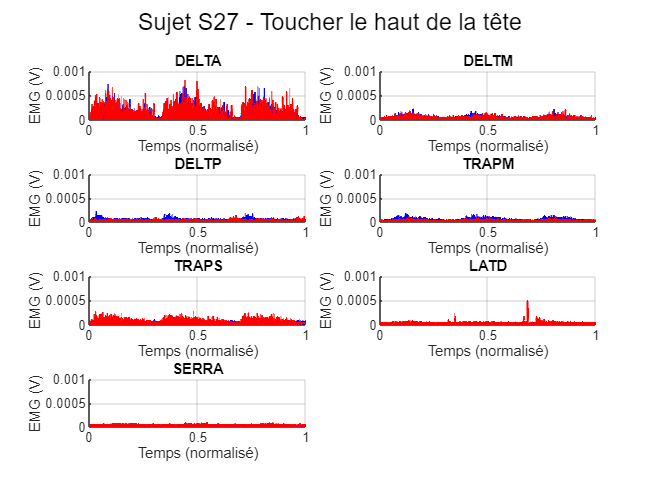

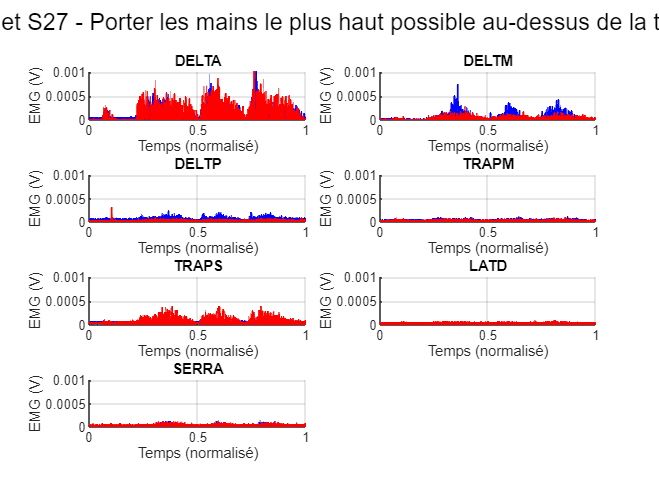

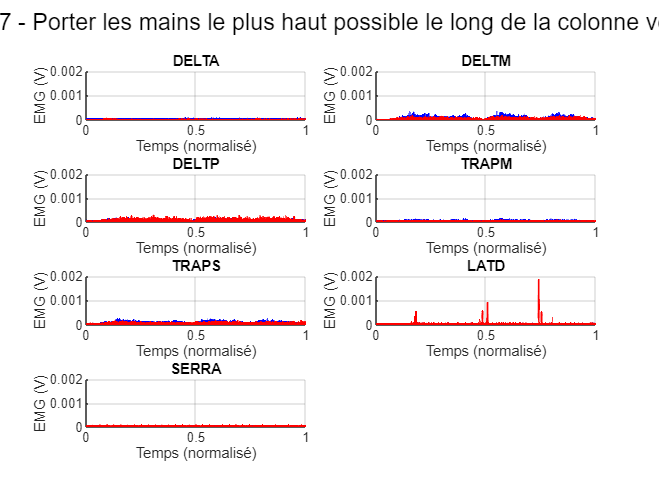

% Appel de la fonction pour obtenir les données brutes

% SAINS
plot_EMG_from_C3D_functional(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Asymptomatic');


% PRE-OPERATOIRE
plot_EMG_from_C3D_functional(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Pre_operation');

% POST-OPERATOIRE
plot_EMG_from_C3D_functional(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Post_operation');

Echelle non normalisée pour tous les muscles (visualisation plus précise du signal)

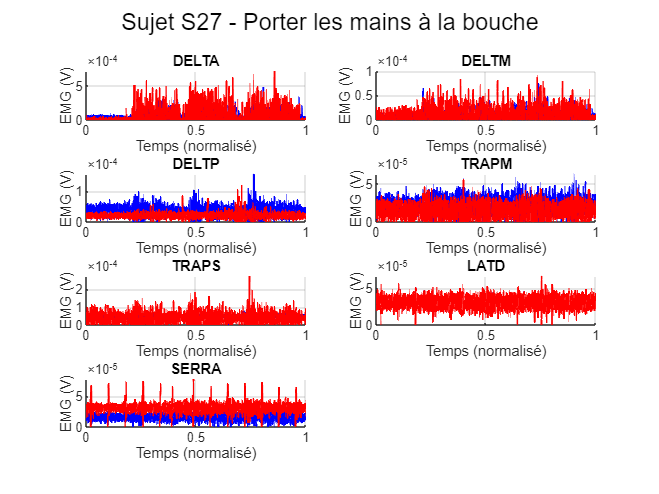

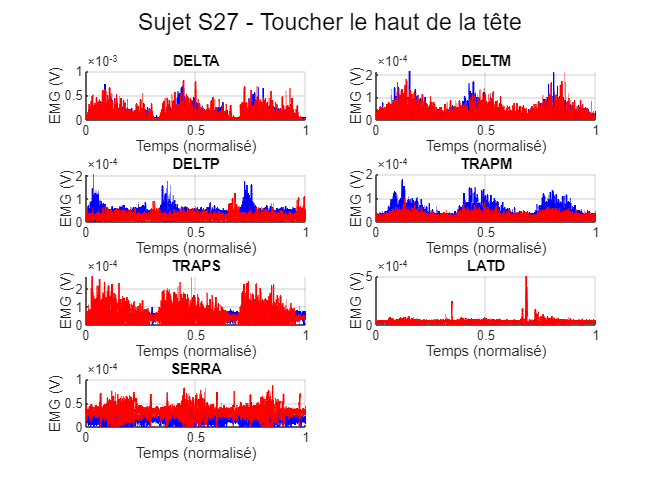

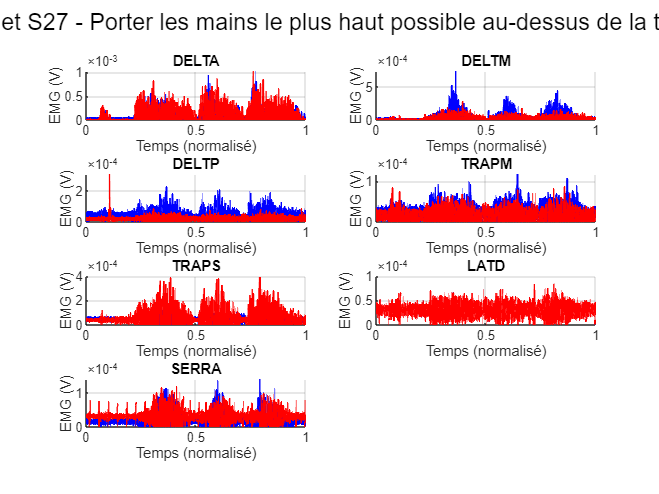

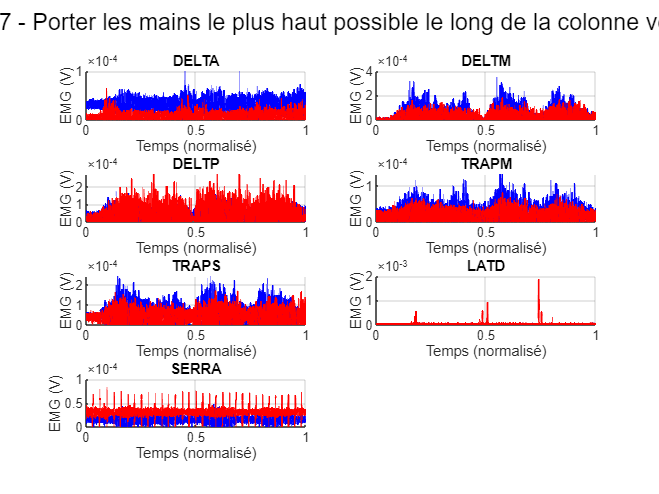

% Appel de la fonction pour obtenir les données brutes

% SAINS
plot_EMG_from_C3D_functional_nnorm(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Asymptomatic');


% PRE-OPERATOIRE
plot_EMG_from_C3D_functional_nnorm(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Pre_operation');

% PRE-OPERATOIRE
plot_EMG_from_C3D_functional_nnorm(subjects, muscles_R, muscles_L, functional_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Post_operation');